clc
clear all
format long

## 时域雷达回波数据

题目要求是10us的脉宽，这里设置一个回波的周期为100us，进行回波的生成。

- 产生时域的回波

real_period_time = 100e-6 ;   %100us
real_single_time = 10e-6 ;   %10us
fs = 10e+6               ;   %10Mhz采样率

%%采样时间处理
t_all = 1/fs:1/fs:real_period_time;
real_signal_length = length(t_all);

t_single = 1/fs:1/fs:real_single_time;

%信号波形生成
pluse_amplitude = 0.3;   %单位V，范围0~5V
real_pluse_signal = pluse_amplitude * rectpuls(t_single);
real_pluse_signal_length = length(real_pluse_signal);
real_idel_signal = [zeros(1,100),real_pluse_signal(1:real_pluse_signal_length),zeros(1,real_signal_length-real_pluse_signal_length-100)];

gaussian_noise_snr = 25;
real_noise_signal = abs(awgn(real_idel_signal,gaussian_noise_snr));


- 绘制理想回波采样图形和加高斯白噪声回波采样图形

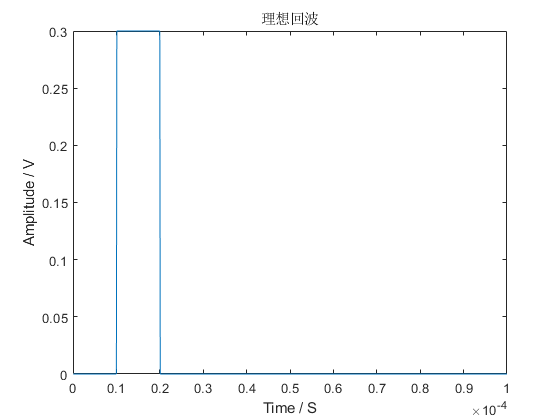

plot(t_all,real_idel_signal);
title("理想回波");
xlabel("Time / S");
ylabel("Amplitude / V");

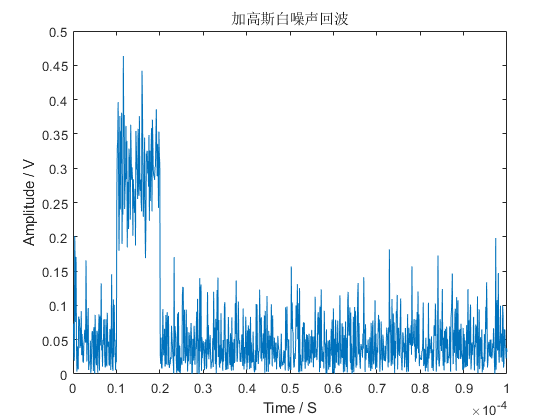


plot(t_all,real_noise_signal);
title("加高斯白噪声回波");
xlabel("Time / S");
ylabel("Amplitude / V");

- 分析单回波信噪比

snr_single_period = snr(real_idel_signal,real_noise_signal-real_idel_signal)

snr_single_period = 4.5850

## 使用非相参积累方法，提高信噪比

waveforms_number = 8

waveforms_number = 8

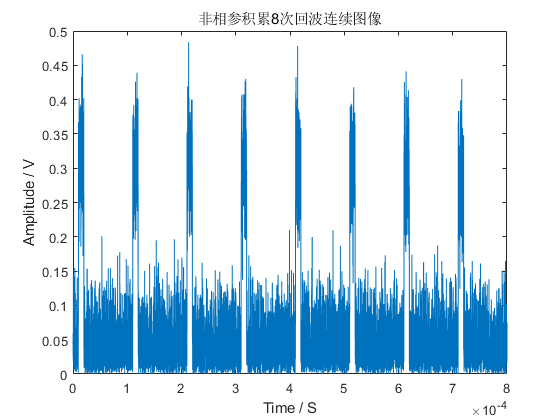

mif_file_data = [];  %用于生成mif的内存
data_acc_result = abs(awgn(real_idel_signal,gaussian_noise_snr));
mif_file_data = [mif_file_data(1:length(mif_file_data)),data_acc_result(1:real_signal_length)];
for number = 1:waveforms_number-1
    real_noise_signal = abs(awgn(real_idel_signal,gaussian_noise_snr));
    data_acc_result = data_acc_result + real_noise_signal;
    mif_file_data = [mif_file_data(1:length(mif_file_data)),real_noise_signal(1:real_signal_length)];
end

data_acc_result = 1/waveforms_number.*data_acc_result;

t_acc_all = 1/fs:1/fs:waveforms_number*real_period_time;
length_t_acc_all = length(t_acc_all);

plot(t_acc_all,mif_file_data);
title("非相参积累8次回波连续图像");
xlabel("Time / S");
ylabel("Amplitude / V");

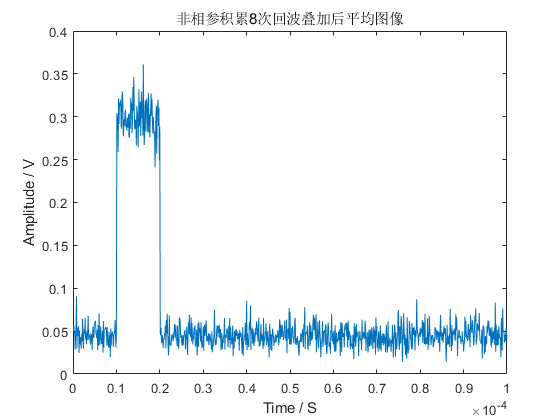



plot(t_all,data_acc_result);
title("非相参积累8次回波叠加后平均图像");
xlabel("Time / S");
ylabel("Amplitude / V");

- 分析非相参累加回波结果信噪比

snr_non_coherent_acc = snr(real_idel_signal,data_acc_result-real_idel_signal)

snr_non_coherent_acc = 6.6407

- 得到非相参积累增益

Gnc = snr_non_coherent_acc/snr_single_period

Gnc = 1.4484

## 生成mif文件


r = [];
for i = 1:length_t_acc_all
    r = [r;ieee_754_double_to_64bits(mif_file_data(i))];
end


fid = fopen('data1.mif','w');
fprintf(fid,'%s\n','DEPTH = 8000;');
fprintf(fid,'%s\n','WIDTH = 64;');
fprintf(fid,'%s\n','ADDRESS_RADIX = DEC;');
fprintf(fid,'%s\n','DATA_RADIX = BIN;');
fprintf(fid,'%s\t','CONTENT');
fprintf(fid,'%s\n','BEGIN');
for i=1:size(r,1)
    fprintf(fid, '%d',i-1);            %address
    fprintf(fid, '%s',' : '); 
    fprintf(fid, '%s',r(i,1));
    fprintf(fid, '%s',r(i,2));
    fprintf(fid, '%s',r(i,3));
    fprintf(fid, '%s',r(i,4));
    fprintf(fid, '%s',r(i,5));
    fprintf(fid, '%s',r(i,6));
    fprintf(fid, '%s',r(i,7));
    fprintf(fid, '%s',r(i,8));
    fprintf(fid, '%s',r(i,9));
    fprintf(fid, '%s',r(i,10));
    fprintf(fid, '%s',r(i,11));
    fprintf(fid, '%s',r(i,12));
    fprintf(fid, '%s',r(i,13));
    fprintf(fid, '%s',r(i,14));
    fprintf(fid, '%s',r(i,15));
    fprintf(fid, '%s',r(i,16));
    fprintf(fid, '%s',r(i,17));
    fprintf(fid, '%s',r(i,18));
    fprintf(fid, '%s',r(i,19));
    fprintf(fid, '%s',r(i,20));
    fprintf(fid, '%s',r(i,21));
    fprintf(fid, '%s',r(i,22));
    fprintf(fid, '%s',r(i,23));
    fprintf(fid, '%s',r(i,24));
    fprintf(fid, '%s',r(i,25));
    fprintf(fid, '%s',r(i,26));
    fprintf(fid, '%s',r(i,27));
    fprintf(fid, '%s',r(i,28));
    fprintf(fid, '%s',r(i,29));
    fprintf(fid, '%s',r(i,30));
    fprintf(fid, '%s',r(i,31));
    fprintf(fid, '%s',r(i,32));
    fprintf(fid, '%s',r(i,33));
    fprintf(fid, '%s',r(i,34));
    fprintf(fid, '%s',r(i,35));
    fprintf(fid, '%s',r(i,36));
    fprintf(fid, '%s',r(i,37));
    fprintf(fid, '%s',r(i,38));
    fprintf(fid, '%s',r(i,39));
    fprintf(fid, '%s',r(i,40));
    fprintf(fid, '%s',r(i,41));
    fprintf(fid, '%s',r(i,42));
    fprintf(fid, '%s',r(i,43));
    fprintf(fid, '%s',r(i,44));
    fprintf(fid, '%s',r(i,45));
    fprintf(fid, '%s',r(i,46));
    fprintf(fid, '%s',r(i,47));
    fprintf(fid, '%s',r(i,48));
    fprintf(fid, '%s',r(i,49));
    fprintf(fid, '%s',r(i,50));
    fprintf(fid, '%s',r(i,51));
    fprintf(fid, '%s',r(i,52));
    fprintf(fid, '%s',r(i,53));
    fprintf(fid, '%s',r(i,54));
    fprintf(fid, '%s',r(i,55));
    fprintf(fid, '%s',r(i,56));
    fprintf(fid, '%s',r(i,57));
    fprintf(fid, '%s',r(i,58));
    fprintf(fid, '%s',r(i,59));
    fprintf(fid, '%s',r(i,60));
    fprintf(fid, '%s',r(i,61));
    fprintf(fid, '%s',r(i,62));
    fprintf(fid, '%s',r(i,63));
    fprintf(fid, '%s',r(i,64));
    fprintf(fid,'%s\n',';');
end
fprintf(fid,'%s\n','END;');


fclose(fid);

